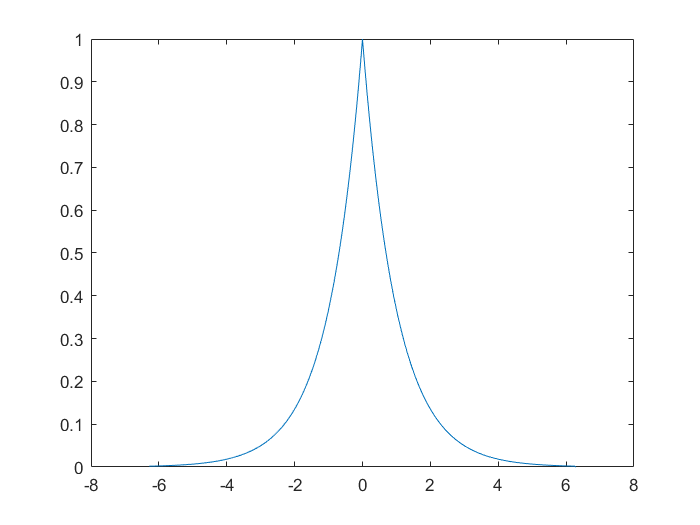

clear
clc
w=-10*pi:0.01*pi:10*pi;
t=-2*pi:0.01*pi:2*pi;
% PROBLEM 1
b=exp(-abs(t));
x=b.*(unit(t+2*pi)-unit(t-2*pi));
plot(t,x);

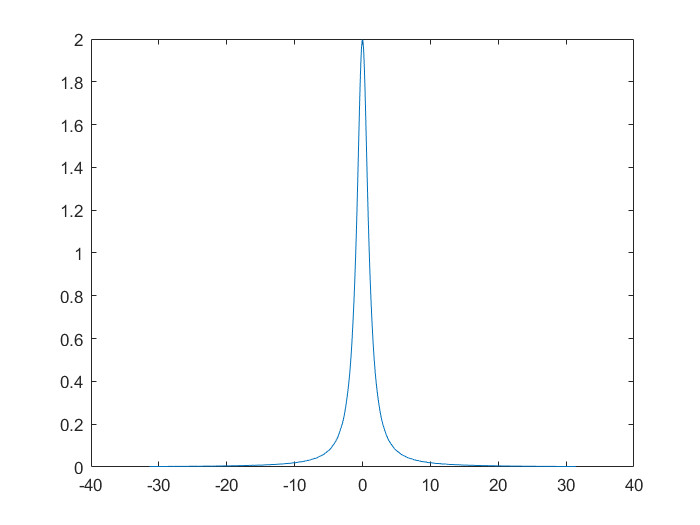



x_w=zeros(size(w));
for i=1:length(w)
    k=w(i);
    basis=exp(-1i*k*t);
    x_w(i)=trapz(t,x.*basis);
end 
figure();
plot(w,abs(x_w));

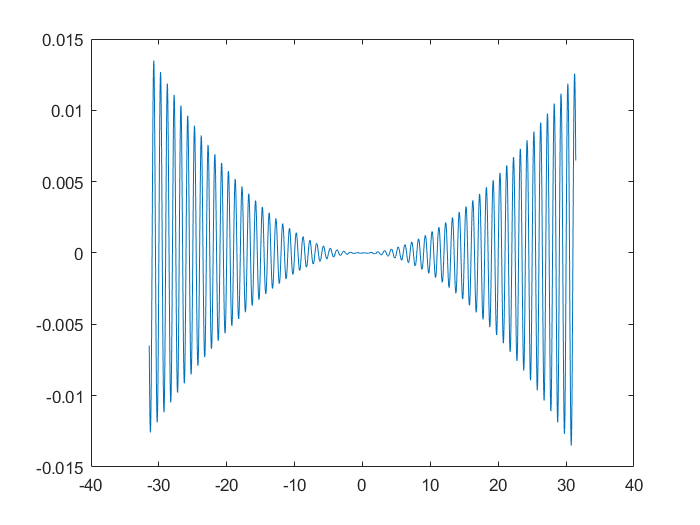

figure();
plot(w,angle(x_w));

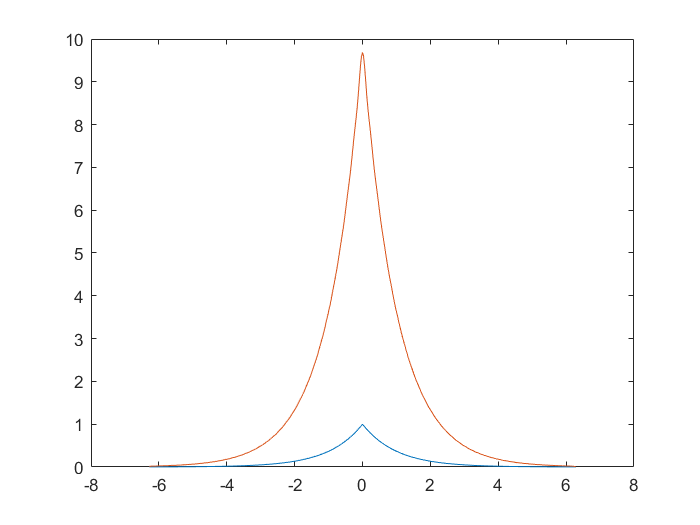



x_t=zeros(size(t));
for i=1:length(t)
    k=t(i);
    basis=exp(1i*w*k);
    x_t(i)=(1/2*pi)*trapz(w,x_w.*basis);
end    
figure();
plot(t,x);
hold on;
plot(t,x_t);